# 2D Heat Flow Simulation

clear, clc;

L = 100;
H = 100;
u = zeros(H, L);

u(1,:) = 0;
u(:,1) = 1;
u(H,:) = 0;
u(:,L) = 1;

colormap("jet")

## Simulate

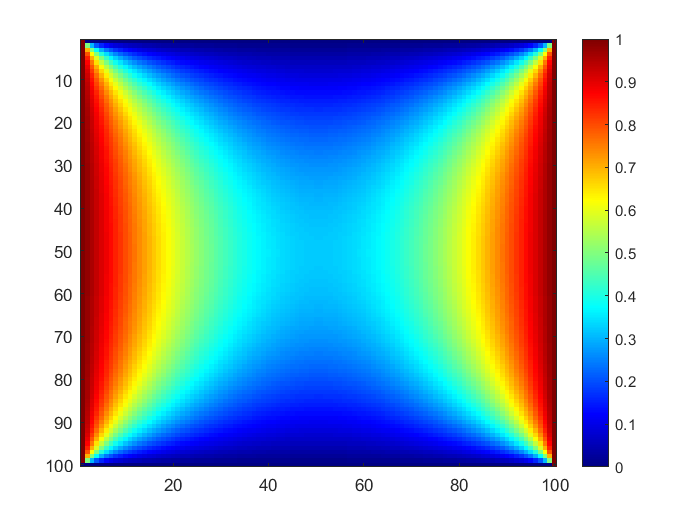

for t=1:3000
    if mod(t, 10) == 0
        imagesc(u);
        colorbar;
        drawnow;
    end
    
%   Laplacian using matlab inbuilt function
    ddu = del2(u);
    u(2:H-1,2:L-1) = u(2:H-1,2:L-1) + ddu(2:H-1,2:L-1);
    
%   Laplacian using Stencils (assuming delta x is equal to 1)
%     ddu = u;
%     for i=2:H-1
%         for j=2:L-1
% %             ddu(i,j) = u(i+1,j) + u(i-1,j) + u(i,j+1) + u(i,j-1) - 4 * u(i,j); % 5pt-Stencil
%             ddu(i,j) = u(i+1,j) + u(i+1,j+1) + u(i+1,j-1) + u(i-1,j) + u(i-1,j+1) + u(i-1,j-1) + u(i,j+1) + u(i,j-1) - 8 * u(i,j); % 8pt-Stencil
%         end
%     end
%     u(2:H-1,2:L-1) = u(2:H-1,2:L-1) + 0.1 * ddu(2:H-1,2:L-1);

%   By making laplace eqn true for each element
%     for i=2:H-1
%         for j=2:L-1
% %             u(i,j) = (u(i+1,j) + u(i-1,j) + u(i,j+1) + u(i,j-1)) / 4; % 5pt-Stencil
%             u(i,j) = (u(i+1,j) + u(i+1,j+1) + u(i+1,j-1) + u(i-1,j) + u(i-1,j+1) + u(i-1,j-1) + u(i,j+1) + u(i,j-1)) / 8; % 8pt-Stencil
%         end
%     end
end